## Periodic Exponential

Let $x_1 \left(t\right)=e^{-\mathrm{at}} \left\lbrack u\left(t\right)-u\left(t-T\right)\right\rbrack$

Using laplace transform, the fourier series can be determined as: 


$$X_k =\frac{1}{T}X_1 \left(\mathrm{jk}\omega_0 \right)=\frac{1-e^{-\mathrm{aT}} }{\mathrm{aT}+\mathrm{j2}\pi \;k}$$


First, define the variables used in the graph in the time domain

clear;
clc;

j = sqrt(-1);
T = 1;
t_max = 3*T;
t_min = -t_max;
dt = T/1000;
t = t_min:dt:t_max;
x = zeros(size(t));

Next Determine the structure of the graph in the time domain

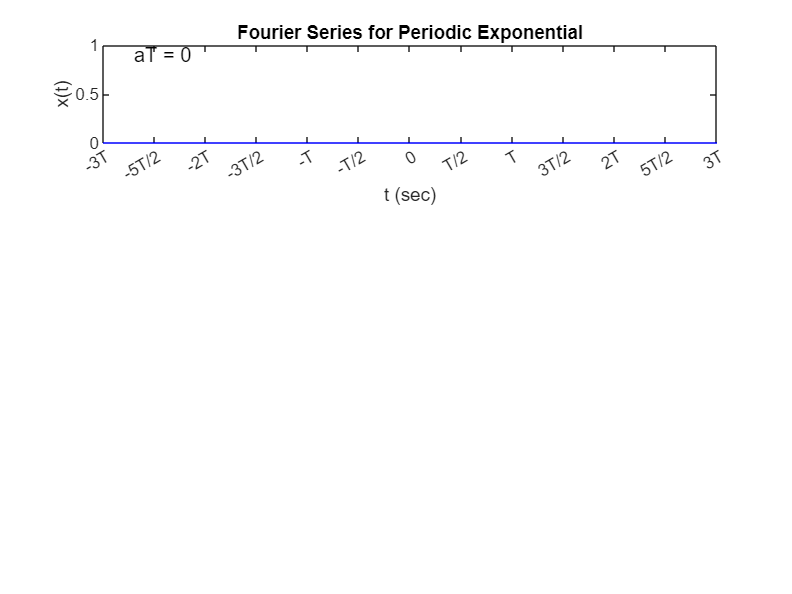

figure(1);
subplot(3,1,1);
h5 = plot(t,x,'b-');
axis([t_min t_max 0 1]);
h6 = text(0.9*t_min,0.9,['aT = 0']);
xlabel('t (sec)');
ylabel('x(t)');
title('Fourier Series for Periodic Exponential');
% location along the x-axis where tick appear
set(gca,'XTick',[-3*T:0.5*T:3*T]); 
% location along the x-axis where tick labels appear
set(gca,'XTickLabel',{'-3T','-5T/2','-2T','-3T/2','-T','-T/2','0','T/2','T','3T/2','2T','5T/2','3T'});

Next, set the structure of the graph of the Fourier coefficients

k_max = 30;
k_min = -k_max;
k = k_min:k_max;
X = zeros(size(k));

subplot(3,1,2);
h7 = stem(k,abs(X),'b','filled');
xlabel('k')
ylabel('|X_k|')
axis([k_min k_max 0 1])

Next, set the structure of the graph for the phase angles

subplot(3,1,3)
h8 = stem(k,angle(X),'r','filled');
xlabel('k')
ylabel('\angle X_k')
axis([k_min k_max -pi/2 pi/2])

Finally, loop through the parameters to generate the Harmonics of the fourier coefficients

for aT = 0.125 : 0.125 : 5
    a = aT/T;
    x = 0;
    for i = -3:2
        subset = (abs(t-(i+0.5)*T) <= T/2);
        t1 = t(subset) - i*T;
        x(subset) = exp(-a*t1);
    end
    
    % function of the fourier series
    X = ( 1 - exp(-aT) ) ./ ( aT + j*2*pi*k);

    set(h5, 'YData', x)
    set(h6, 'String', ['aT = ' num2str(aT)])
    
    set(h7,'YData', abs(X))
    set(h8,'YData', angle(X))
    
    waitforbuttonpress


end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted